A = linsys.A;
B = linsys.B;
C = linsys.C;
D = linsys.D;

isstable(linsys)

ans = logical
   0


eig(A)

ans =    0.0000 + 0.0000i
   0.0000 + 0.0011i
   0.0000 - 0.0011i
  -0.0000 + 0.0011i
  -0.0000 - 0.0011i
  -0.0000 + 0.0000i


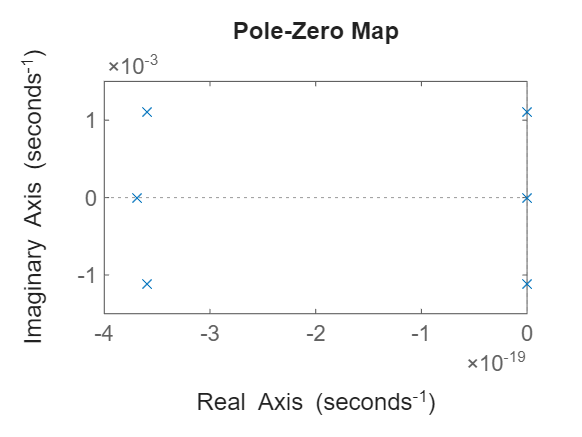

figure;
pzplot(linsys)


%% LQR CONTROLLER
% Penalising state
Q1 = 0.01; 
Q2 = 0.01; 
Q3 = 0.01; 
Q4 = 0.01;
Q5 = 0.01;
Q6 = 0.01;

Q = [Q1,0,0,0,0,0;
     0,Q2,0,0,0,0;
     0,0,Q3,0,0,0;
     0,0,0,Q4,0,0;
     0,0,0,0,Q5,0;
     0,0,0,0,0,Q6];

% Penalising control effort
R = 10000*eye(3);

K = lqr(linsys,Q,R)

K =     0.0010   -0.0000   -0.0001    0.0892   -0.0000   -0.0000
    0.0000    0.0010    0.0000    0.0000    0.0892    0.0000
    0.0001   -0.0000    0.0010   -0.0000    0.0000    0.0899


cls = ss(A-B*K,B,C,D)


cls =
 
  A = 
               x1          x2          x3          x4          x5          x6
   x1           0           0           0           1           0           0
   x2           0           0           0           0           1           0
   x3           0           0           0           0           0           1
   x4  -0.0002488   2.517e-19   2.478e-05    -0.02231   1.482e-17    0.002222
   x5  -1.215e-20    -0.00025  -1.119e-20   -2.18e-18    -0.02231  -2.234e-18
   x6  -2.478e-05   8.256e-21  -0.0002488   -0.002205  -3.188e-18    -0.02247
 
  B = 
         u1    u2    u3
   x1     0     0     0
   x2     0     0     0
   x3     0     0     0
   x4  0.25     0     0
   x5     0  0.25     0
   x6     0     0  0.25
 
  C = 
       x1  x2  x3  x4  x5  x6
   y1   1   0   0   0   0   0
   y2   0   1   0   0   0   0
   y3   0   0   1   0   0   0
   y4   0   0   0   1   0   0
   y5   0   0   0   0   1   0
   y6   0   0   0   0   0   1
 
  D = 
       u1  u2  u3
   y1   0   0  

isstable(cls)

ans = logical
   1


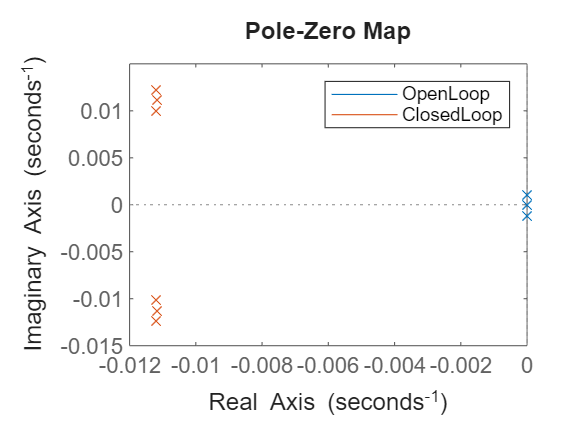


figure; hold on;
pzplot(linsys)
pzplot(cls)
legend('OpenLoop','ClosedLoop')

eig(cls.A)

ans =   -0.0112 + 0.0123i
  -0.0112 - 0.0123i
  -0.0112 + 0.0101i
  -0.0112 - 0.0101i
  -0.0112 + 0.0112i
  -0.0112 - 0.0112i


Along = [A(1,1),A(1,3:4),A(1,6);
        A(3,1),A(3,3:4),A(3,6);
        A(4,1),A(4,3:4),A(4,6);
        A(6,1),A(6,3:4),A(6,6)];
Blong = [B(1,:);B(3,:);B(4,:);B(6,:)]

Blong =          0         0         0
         0         0         0
    0.2500         0         0
         0         0    0.2500


eig(Along)

ans =    0.0000 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 + 0.0011i
  -0.0000 - 0.0011i


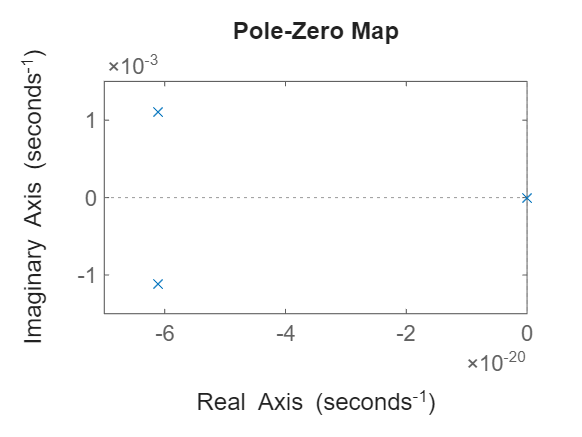


longsys = ss(Along,Blong,eye(4),0);

figure;
pzplot(longsys)